# MULTIBODY SOLUTION - EXAM 09/07/2025

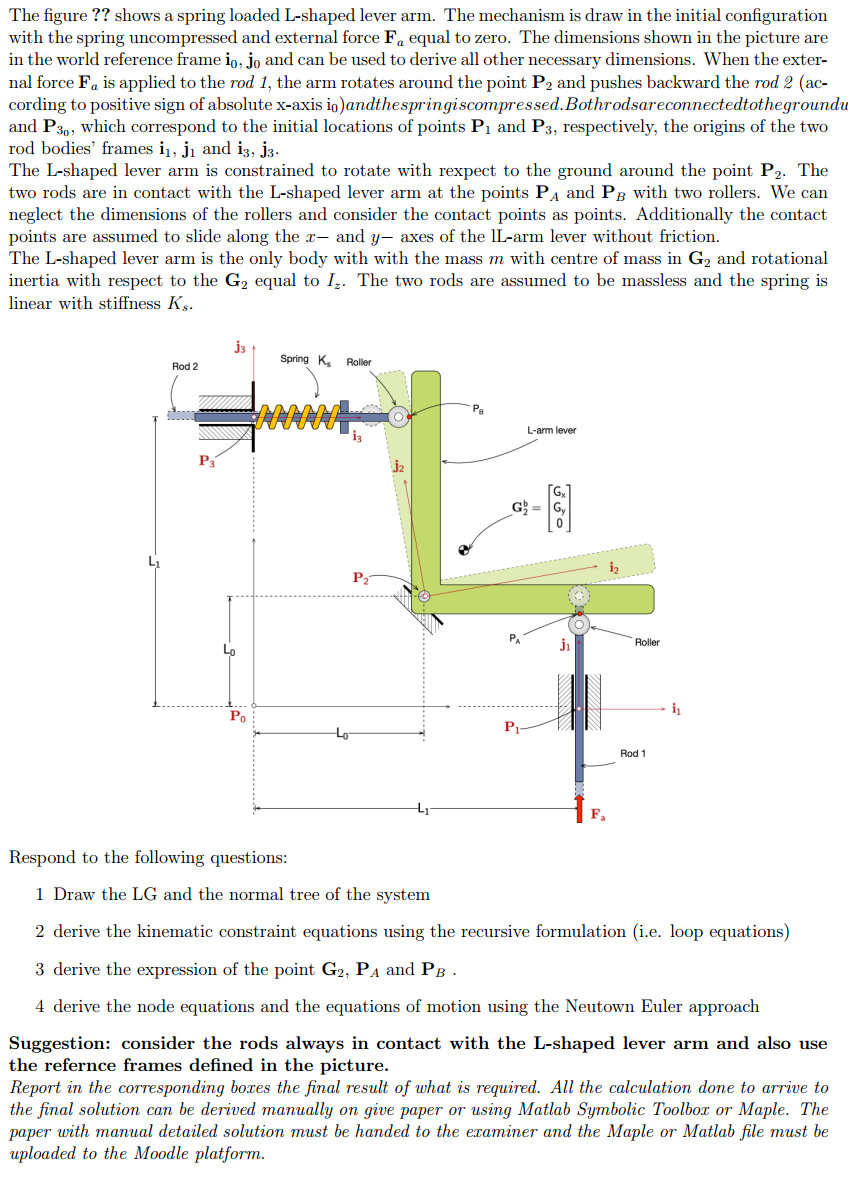

*Both rods are connected to the ground using prismatic joints in *$P_{1_0}$* and *$P_{3_0}$

**!! NOTE**: rollers are **CAM JOINTS**, modeled as a combination of a **PRISMATIC + REVOLUTE JOINT**

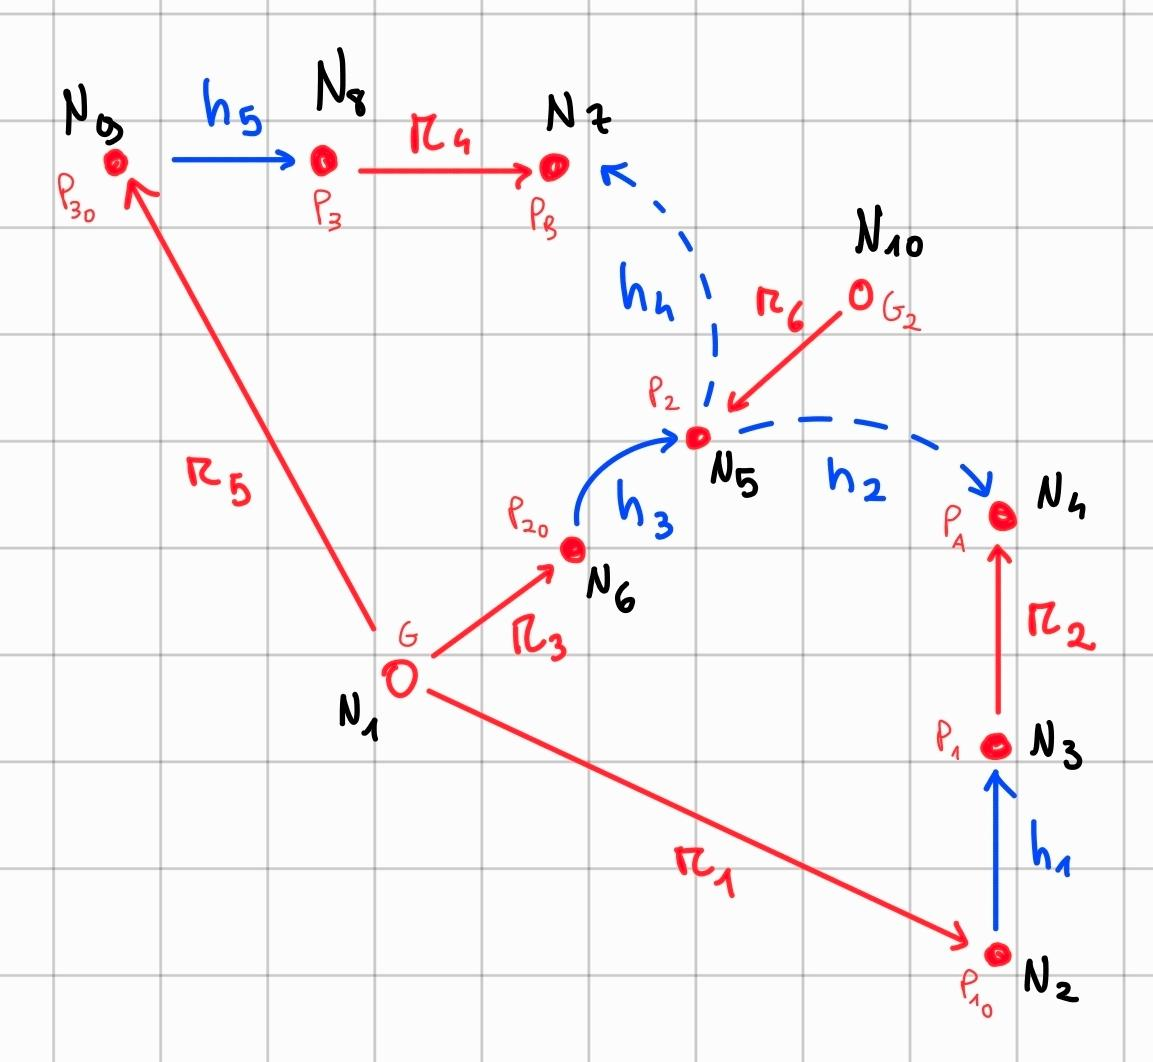

### 0) Sytem data and definition

clear;
clc;
close all;
syms t
addpath('MBLibs\');

System unknowns and parameters

% Unknowns
syms theta_1(t) s_1(t) s_2(t)
% Given parameters
syms L_0 L_1 G_x G_y

### 1) Kinematic equations

#### Bodies

L-shaped lever arm

R1 = rotate3('Z', theta_1(t));
b = [G_x; G_y; 0];

#### Joints

J1 right prismatic

j1 = [0; 1; 0];
h1 = s_1(t)*j1

$$h1 = \left(\begin{array}{c} 0\\ s_{1}\left(t\right)\\ 0 \end{array}\right)$$

J2 right cam

syms theta_J2(t)
RJ2 = rotate3('Z', theta_J2(t));
h2 = RJ2 * (s_1(t)*j1)

$$h2 = \left(\begin{array}{c} -\sin\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,s_{1}\left(t\right)\\ \cos\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,s_{1}\left(t\right)\\ 0 \end{array}\right)$$

J3 revolute

syms theta_J3(t)
RJ3 = rotate3('Z', theta_J3(t))

$$RJ3 = \left(\begin{array}{ccc} \cos\left(\theta_{\mathrm{J3}}\left(t\right)\right) & -\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right) & 0\\ \sin\left(\theta_{\mathrm{J3}}\left(t\right)\right) & \cos\left(\theta_{\mathrm{J3}}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

h3 = zeros(3,1)

h3 =      0
     0
     0


J4 left cam

syms theta_J4(t)
i3 = [1; 0; 0];
RJ4 = rotate3('Z', theta_J4(t));
h4 = RJ4 * (s_2(t)*i3)

$$h4 = \left(\begin{array}{c} \cos\left(\theta_{\mathrm{J4}}\left(t\right)\right)\,s_{2}\left(t\right)\\ \sin\left(\theta_{\mathrm{J4}}\left(t\right)\right)\,s_{2}\left(t\right)\\ 0 \end{array}\right)$$

J5 left prismatic

h5 = s_2(t)*i3

$$h5 = \left(\begin{array}{c} s_{2}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

#### Arm-links

% With simple translations
% r1
r1 = [L_1; 0; 0]

$$r1 = \left(\begin{array}{c} L_{1}\\ 0\\ 0 \end{array}\right)$$

% r3
r3 = [L_0; L_0; 0]

$$r3 = \left(\begin{array}{c} L_{0}\\ L_{0}\\ 0 \end{array}\right)$$

% r5
r5 = [0; L_1; 0]

$$r5 = \left(\begin{array}{c} 0\\ L_{1}\\ 0 \end{array}\right)$$


% Other arm-links (follow the kinematic chain to project to global frame)
% r2
ra2 = [0; L_0; 0];
r2 = RJ3 * RJ2 * ra2

$$r2 = \left(\begin{array}{c} -L_{0}\,\left(\cos\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)+\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J2}}\left(t\right)\right)\right)\\ -L_{0}\,\left(\sin\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)-\cos\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\right)\\ 0 \end{array}\right)$$

% r4
ra4 = [L_0; 0; 0];
r4 = RJ3 * RJ4 * ra4

$$r4 = \left(\begin{array}{c} -L_{0}\,\left(\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J4}}\left(t\right)\right)-\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\cos\left(\theta_{\mathrm{J4}}\left(t\right)\right)\right)\\ L_{0}\,\left(\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J4}}\left(t\right)\right)+\cos\left(\theta_{\mathrm{J4}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)\right)\\ 0 \end{array}\right)$$

% r6
ra6 = [-G_x; -G_y; 0];
r6 = RJ3*ra6

$$r6 = \left(\begin{array}{c} G_{y}\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)-G_{x}\,\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\\ -G_{x}\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)-G_{y}\,\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\\ 0 \end{array}\right)$$

### 2) Loop equations

#### **R-Tree**

Phi_thetaJ2 = theta_J2 == -theta_J3;
Phi_thetaJ4 = theta_J4 == -theta_J3;
Phi_thetaJ3 = theta_J3 == theta_1;
Phi_thetaJi = [Phi_thetaJ2; Phi_thetaJ4; Phi_thetaJ3]

$$Phi\_thetaJi(t) = \left(\begin{array}{c} \theta_{\mathrm{J2}}\left(t\right)=-\theta_{\mathrm{J3}}\left(t\right)\\ \theta_{\mathrm{J4}}\left(t\right)=-\theta_{\mathrm{J3}}\left(t\right)\\ \theta_{\mathrm{J3}}\left(t\right)=\theta_{1}\left(t\right) \end{array}\right)$$

#### T-Tree

First loop (solve for cut-joint J2 edge)

eq_cut1 = h2 == r1 + h1 + r2 - h3 - r3

$$eq\_cut1 = \left(\begin{array}{c} -\sin\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,s_{1}\left(t\right)=L_{1}-L_{0}-L_{0}\,\left(\cos\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)+\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J2}}\left(t\right)\right)\right)\\ \cos\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,s_{1}\left(t\right)=s_{1}\left(t\right)-L_{0}-L_{0}\,\left(\sin\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)-\cos\left(\theta_{\mathrm{J2}}\left(t\right)\right)\,\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\right)\\ 0=0 \end{array}\right)$$

Project onto reaction space of the joint J2

ij2 = get_unit_vector3('X', RJ2);
tmp = simplify(expand(eq_cut1.'*ij2));
tmp = subs(tmp, lhs(Phi_thetaJi), rhs(Phi_thetaJi));
Phi_J2 = subs(tmp, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

$$Phi\_J2 = L_{0}\,\left(\sin\left(\theta_{1}\left(t\right)\right)+\sqrt{2}\,\sin\left(\frac{\pi }{4}-\theta_{1}\left(t\right)\right)\right)=L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)-\sin\left(\theta_{1}\left(t\right)\right)\,s_{1}\left(t\right)$$

Second loop (solve for cut-joint J4 edge)

eq_cut2 = h4 == r5 + h5 + r4 - h3 - r3

$$eq\_cut2 = \left(\begin{array}{c} \cos\left(\theta_{\mathrm{J4}}\left(t\right)\right)\,s_{2}\left(t\right)=s_{2}\left(t\right)-L_{0}-L_{0}\,\left(\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J4}}\left(t\right)\right)-\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\cos\left(\theta_{\mathrm{J4}}\left(t\right)\right)\right)\\ \sin\left(\theta_{\mathrm{J4}}\left(t\right)\right)\,s_{2}\left(t\right)=L_{1}-L_{0}+L_{0}\,\left(\cos\left(\theta_{\mathrm{J3}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J4}}\left(t\right)\right)+\cos\left(\theta_{\mathrm{J4}}\left(t\right)\right)\,\sin\left(\theta_{\mathrm{J3}}\left(t\right)\right)\right)\\ 0=0 \end{array}\right)$$

Project onto reaction space of J4

jj4 = get_unit_vector3('Y', RJ4);
tmp = simplify(expand(eq_cut2.'*jj4));
tmp = subs(tmp, lhs(Phi_thetaJi), rhs(Phi_thetaJi));
Phi_J4 = subs(tmp, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

$$Phi\_J4 = L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)=L_{0}\,\cos\left(\theta_{1}\left(t\right)\right)-\sin\left(\theta_{1}\left(t\right)\right)\,s_{2}\left(t\right)$$

### CoM Kinematics

In this case the two rods are considered massless, so only express position, acceleration and angular velocity of the CoM of the lever arm (G2 in the diagrams)

G2 = subs(r3+h3-r6, lhs(Phi_thetaJi), rhs(Phi_thetaJi))

$$G2 = \left(\begin{array}{c} L_{0}-G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)+G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\\ L_{0}+G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)+G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

VG2 = diff(G2, t);
% Acceleration
AG2 = diff(VG2,t);
% Reduce to first order derivative
syms theta_1dot(t)
AG2 = subs(AG2, diff(theta_1(t),t), theta_1dot(t))

$$AG2 = \left(\begin{array}{c} G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}-G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}-G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)-G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)\\ G_{x}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)-G_{x}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}-G_{y}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\theta_{\mathrm{1dot}}\left(t\right)}^{2}-G_{y}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{1dot}}\left(t\right)\\ 0 \end{array}\right)$$

% Angular velocity
tmp = subs(simplify(RJ3.'*diff(RJ3,t)), lhs(Phi_thetaJi), rhs(Phi_thetaJi)); % Skew symm matrix
ang_vel1 = [tmp(3,2); tmp(1,3); tmp(2,1)] 

$$ang\_vel1 = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right) \end{array}\right)$$

**TODO**: position and angular velocity of P_A, P_B, P_2

### 3) Equations of Dynamics

#### Constitutive eq. of Bodies

#### Constitutive eq. of Joints

#### Constitutive eq. of External forces/torque drivers

### Node equations

#### **Newton equations (translational balance)  ("N")**

#### Euler equations (rotational balance) ("E")

### 4) Assembling the DAE system: final equations of motion